%load matlab workspace file (__.mat)
tt1=(tf(10000:end)); %discard first few iterates manually
figure
%h = histogram(tt1,200)
hold on
%fitdist(tt1(:),'Normal')
dh = 0.01;
x = 0:dh:1.5;
pdKern = fitdist(tt1','kernel')

pdKern =   KernelDistribution

    Kernel = normal
    Bandwidth = 0.0178122
    Support = unbounded


p1=pdf(pdKern,x)

p1 =    0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000005   0.000000000000211   0.000000000007032   0.000000000170947   0.000000003032409   0.000000039249130   0.000000396322085   0.000002826676049   0.000014901227703   0.000058977649068   0.000178460776327   0.000427944875858   0.000869042545862   0.001635776147314   0.003055211593946   0.005658751739488   0.010137409733673   0.017524064001376   0.029655289069737   0.049277647892798   0.079369114033242   0.121998189910421   0.177593270396542   0.244940492012724   0.321600898991665   0.404826683498129   0.492408884670368   0.581578880056100   0.666773817729774   0.740216364887121   0.795349625178025   0.829395294259055   0.843740987521208   0.842487195995603   0.829156844801024   0.8043582680

plot(x,p1,'LineWidth', 2)
h1 = histogram(tt1,'Normalization','pdf')

h1 =   Histogram with properties:

             Data: [1×60001 double]
           Values: [1×89 double]
          NumBins: 89
         BinEdges: [1×90 double]
         BinWidth: 0.020000000000000
        BinLimits: [0.260000000000000 2.040000000000000]
    Normalization: 'pdf'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


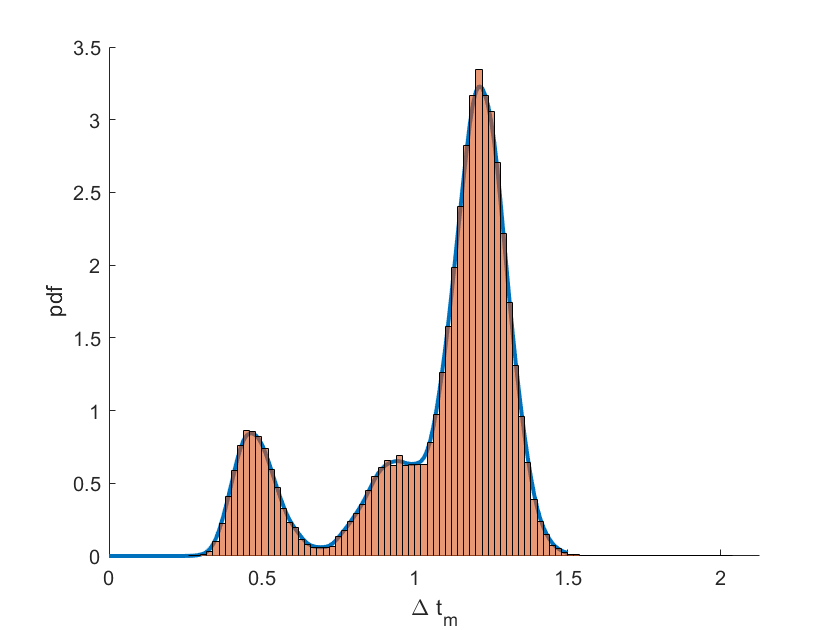

hold off;
%ax = gca;
%z = linspace(ax.XLim(1), ax.XLim(2), length(tt1));
%plot(z, normpdf(z), 'LineWidth', 2)
xlabel("{\Delta t_m}")
ylabel("pdf")